clearvars;

file = 'chirp_80';
load ([file '.mat']);
load 'bandpass.mat';

**Plot the noisy EEG and it's power spectral density**

len = length(data)/2;

sampling_rate = 10000;
total_duration_seconds = len / sampling_rate;
time_axis = 0:1/sampling_rate:total_duration_seconds-(1/sampling_rate);

recorded_eeg = data(len+1:end);
stimulus = data(1:len);

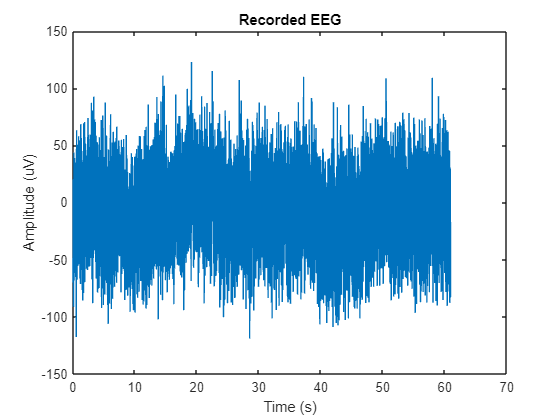

figure;
plot(time_axis,(recorded_eeg/10^(-6)));
xlabel("Time (s)");
ylabel("Amplitude (uV)");
title("Recorded EEG");

Initializing Window Designer....

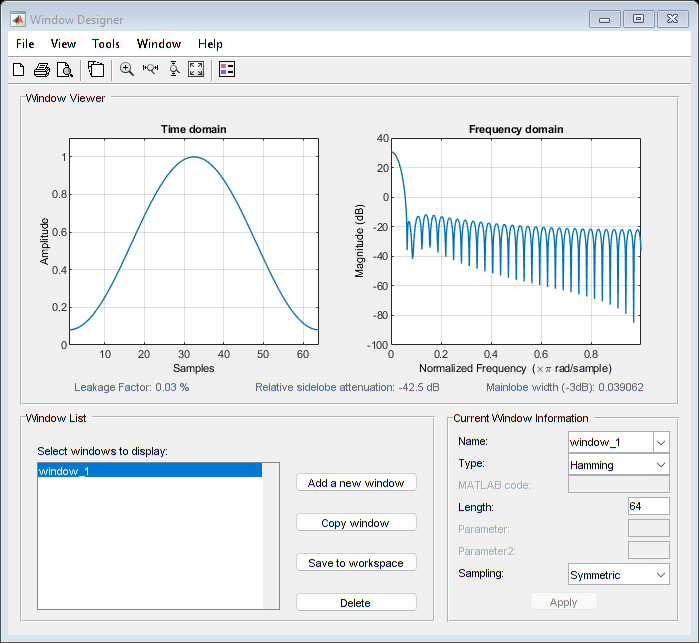

. done. 


nfft = len;
[pxx_noisyEEG,f_noisyEEG] = periodogram(recorded_eeg,window,nfft,sampling_rate);

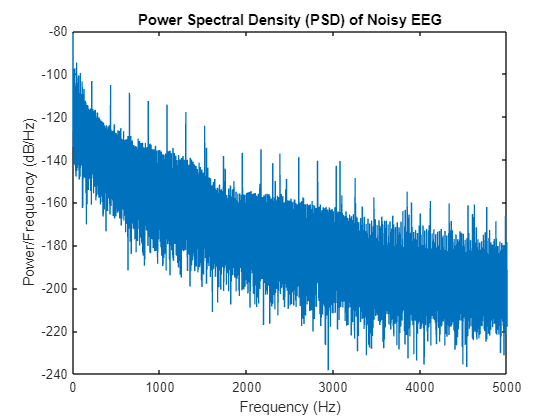


figure;
plot(f_noisyEEG, 10*log10(pxx_noisyEEG)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of Noisy EEG');

**Applying bandpass filter of 100-3000 hz**

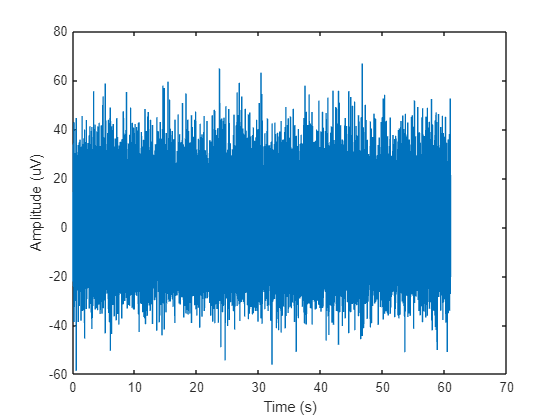

filtered_signal = filtfilt(bandpass,1, recorded_eeg);

figure;
plot(time_axis,filtered_signal/(10^-6));
xlabel("Time (s)");
ylabel("Amplitude (uV)");

Initializing Window Designer....

. done. 


[pxx_filtEEG,f_filtEEG] = periodogram(filtered_signal,window,nfft,sampling_rate);

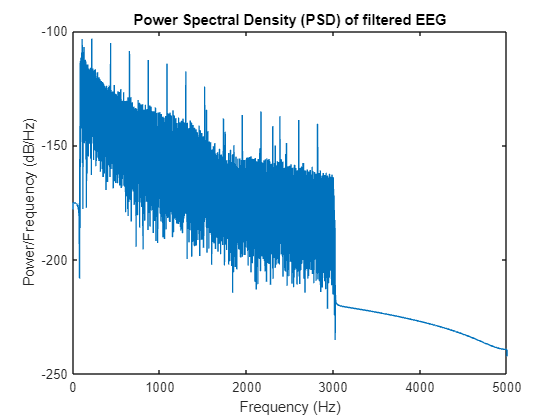


figure;
plot(f_filtEEG, 10*log10(pxx_filtEEG)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density (PSD) of filtered EEG');

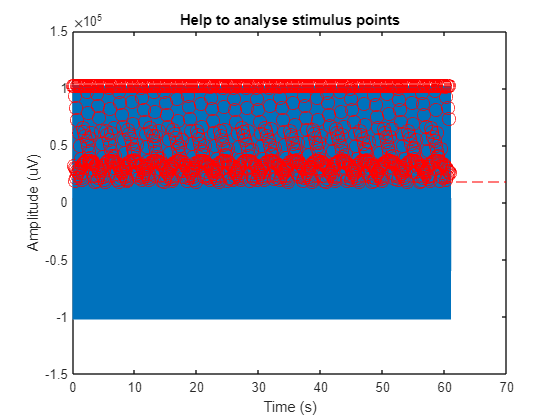

if contains(file, 'chirp')
    if strcmp(file, 'chirp_40')
        stimulus_threshold = 4100;
    elseif strcmp(file, 'chirp_60')
        stimulus_threshold = 5000;
    elseif strcmp(file, 'chirp_80')
        stimulus_threshold = 18000;
    end
    vertical_lines_indices = find(stimulus/10^(-6) > stimulus_threshold);

elseif contains(file, 'click')
    if strcmp(file, 'click_40')
        stimulus_threshold = 2500;
    elseif strcmp(file, 'click_60')
        stimulus_threshold = 0;
    elseif strcmp(file, 'click_80')
        stimulus_threshold = 0;
    end
    vertical_lines_indices = find(stimulus/10^(-6) < stimulus_threshold);

end

min_distance = 300;

% Find indices where amplitudes exceed the threshold

stim_point = zeros(length(vertical_lines_indices), 1);

% stim_point(1) = vertical_lines_indices(1);
j = 1;

for i = 1:length(vertical_lines_indices)-1
    if vertical_lines_indices(i+1) - vertical_lines_indices(i) > min_distance
        stim_point(j) = vertical_lines_indices(i);
        j = j + 1;
    end
end

% Remove unused entries from stim_point
stim_point = stim_point(1:j-1);

figure;
plot(time_axis, (stimulus/10^(-6)));
hold on;
yline(stimulus_threshold, 'r--', 'LineWidth', 0.1);
plot(time_axis(stim_point), (stimulus(stim_point)/10^(-6)), 'ro', 'MarkerSize', 10);

epochs = zeros(450,length(stim_point));

k = 0;
for i=1:length(stim_point)
    k = k + 1;
    if (stim_point(k)+299 <= length(recorded_eeg) && stim_point(k)-150 >=1)
        epochs(:,k) = recorded_eeg((stim_point(i)-150:stim_point(i)+299));
    end
end

xlabel("Time (s)");
ylabel("Amplitude (uV)");
title('Help to analyse stimulus points');

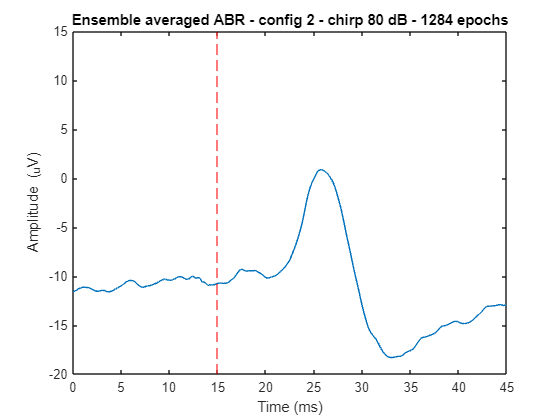

figure;
ABR = mean(epochs(:,(1:length(stim_point))),2);
time_= 0:1/sampling_rate:(length(ABR)/sampling_rate)-(1/sampling_rate);
plot(time_/10^-3,mean(epochs(:,(1:length(stim_point))),2)/10^(-6));
hold on;
xline(time_(151)/10^-3, 'r--', 'LineWidth', 0.1);

ylim([-20 15]);

characters = char(file);

title_text = sprintf("Ensemble averaged ABR - config 2 - %s dB - %d epochs", [characters(1:5) ' ' characters(7:8)], length(epochs));
title(title_text);
xlabel("Time (ms)");
ylabel("Amplitude (_uV)")

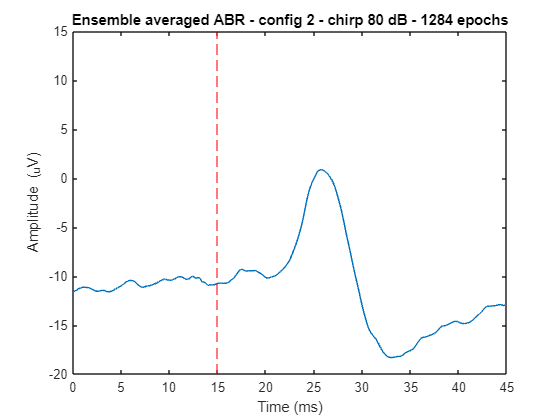

fileName = sprintf("Config 2 - %s dB.png", [characters(1:5) ' ' characters(7:8)]); 
filePath = fullfile(pwd, fileName);  

saveas(gcf,filePath)